# Laboratorio 1

## Integrantes: Mateo Fernandez (202320768), Gabriela Villalba (202411276) y Gabriel Sanchez (202420981)

clc;
clearvars;
close all;
format long g

carpetaActual = pwd;
versionMATLAB = version;
variablesIniciales = whos;

## Punto 1

d = [2 0 2 4 2 0 9 8 1];

p = d(1,7)+2;
q = d(1,8)+3;
r = d(1,9)+4;
theta = 10*d(1,4)+d(1,5);

E1_grados = (sind(theta)+(cosd(p+q))^2+r^(-1))/(log10(p^2+q^2+10)+(log(r+20))/(sqrt(p^2+q^2+r^2)));
E2_grados = ((p+q)^2/(tand(theta+5)))*log(r+1)+power(((p+r)*exp(-q/10))/log2(p*q+r+2),1/3);

E1_radianes = (sin(theta)+(cosd(p+q))^2+r^(-1))/(log10(p^2+q^2+10)+(log(r+20))/(sqrt(p^2+q^2+r^2)));
E2_radianes = ((p+q)^2/(tan(theta+5)))*log(r+1)+power(((p+r)*exp(-q/10))/log2(p*q+r+2),1/3);

log(0)

ans =   -Inf


sqrt(-1)

ans =                           0 +                     1i


A pesar de que ciertas funciones tienen restricciones en su dominio como los logaritmos o las raices, Matlab puede llegar a manejar de forma completa algunas de estas funciones. Por ejemplo calcular el logaritmo natural de 0 resulta en -Inf, pero no en error y la raiz cuadrada de -1 resulta en 1i y no en error, por lo que a pesar de que pueden dar valores poco utiles, no afecta en la compilacion del programa.

%Presente ambos resultados y explique el efecto de interpretar θ con una unidad angular diferente.
E1_grados

E1_grados =          0.665334616880019



E1_radianes

E1_radianes =         0.0550911188098749


El hecho de utilizar sind vs sin puede tener implicaciones significativas dentro del calculo. La función seno no es lineal y un cambio ligero en el calculo de este puede tener implicaciones significativas, por ejemplo, el angulo de 45º es 1/8 de circulo por lo que el seno de 45º es sqrt(2)/2, sin embargo 45 radianes es el equivalente de aproximadamente 7.16 vueltas al circulo unitario, lo que es aproximadamente 57º. Por lo que comprender bajo que escala se mide el angulo es importante para prevenir inconsistencias numericas.

% Presente una tabla con p, q, r, θ, E1 y E2, incluyendo la clase de dato. Muestre los resultados con format

T = table(p', q', r', theta', E1_grados', E2_grados', E1_radianes', E2_radianes', ...
    'VariableNames', {'p', 'q', 'r', 'theta', 'E1_grados', 'E2_grados', 'E1_radianes', 'E2_radianes'});
T

T = 1×8 table
    p     q     r    theta        E1_grados           E2_grados           E1_radianes          E2_radianes   
    __    __    _    _____    _________________    ________________    __________________    ________________

    11    11    5     42      0.665334616880019    809.600804013371    0.0550911188098749    -6963.0999176656


format short
E1_grados

E1_grados = 0.6653

El formato short se encarga de mostrar numeros con maximo 4 cifras decimales, es estético y solo afecta lo que muestra la consola, internamente los numeros se manejan como doubles y son los tipos de datos numericos estandar del programa. Estos proveen alrededor de 15-17 cifras decimales de precisión. Matlab al ser un lenguaje de programación con tipado dinamico (asigna el tipo de variable de forma dinamica) no se tiene que especificar el tipo de dato a ingresar, sin embargo si se requiere o se prefiere algún tipo de dato en especifico siempre se pueden convertir los datos double a single o a enteros o algun dato de preferencia.

format long;
class(E1_grados)

ans = 'double'

E1_grados

E1_grados =    0.665334616880019


Por el contrario el formato long se encarga de mostrar resultados con hasta 15 cifras decimales

fprintf("%4.6f", E1_grados)

0.665335

fprintf("%2.8f", E1_grados)

0.66533462

En el formato fprintf permite escribir datos a un archivo de texto o imprimir directamente a la consola si se omite la ruta al archivo de texto a editar. De manera similar al lenguaje de programacion C, se utilizan ciertos operadores dentro de un string, en este caso el % indica "reemplazar por cierta variable" e inmediatamente después se especifica el tipo de variable y/o el formato con el que se muestra. Como se está manejando un numero (tipo float) se especifican la cantidad de numeros enteros a mostrar y la cantidad de decimales fijos a mostrar. Si se quiere mostrar un entero se utilizaría %d, o si se quisiese en notación cientifica se utilizaria %e, o una cadena de caracteres sería %s.

## Punto 2

A = [p q r; q+r p+1 q-1; r-p q+2 p+r]

A =     11    11     5
    16    12    10
    -6    13    16



B = [r+1 q-1 q; p+q r 1; q-r p+2 r+2]

B =      6    10    11
    22     5     1
     6    13     7



A + B

ans =     17    21    16
    38    17    11
     0    26    23


El Significado Matematico de A + B es simplemente la suma individual de cada uno de los indices correspondientes, es decir el indice a11 se suma con b11 y el indice a12 se suma con b12 y asi sucesivamente.

A*B

ans =    338   230   167
   420   350   258
   346   213    59


Al utilizarse la multiplicación entre matrices, se define que el resultado entre la multiplicación de matrices tendra una dimesión a*c cuanto las matrices de entrada tienen dimensión (a,b*b,c), note que si la dimension del "ancho" de la primera matriz no coincide con la dimension del "alto" de la segunda matriz la multiplicación matricial NO está definida. La multiplicación matricial NO es conmutativa debido al algoritmo que se utiliza para calcularla (fila*columna) en donde al cambio en el orden de los indices afecta el resultado de la multiplicación fila*columna. Para verificar, se calcula el resultado c11 (el primer indice de ans, que en este caso es 338).

A(1,:)*B(:,1)

ans =    338


Se accede a la primera fila de la matriz A utilizando slicing, es decir se accede a la primera fila y se guardan TODOS los valores de esa columna con el operador :

De manera similar, se accede la primera columna de la matriz B utilizando solamente la primera columna, pero se almacenan TODAS las filas. Como el resultado de ambas operaciones da un vector, se pueden multiplicar directamente para obtener el producto punto entre estos dos vectores que da el mismo resultado que se obtuvo multiplicando las matrices completas de A y de B.

B*A

ans =    160   329   306
   316   315   176
   232   313   272



A.*B

ans =     66   110    55
   352    60    10
   -36   169   112


El producto de A .* B es equivalente a la multiplicación individual entre los indices de las matrices, es decir de manera similar a A+B, se obtiene que a11*b11 es igual al primer indice del resultado. De manera similar, el segundo indice resultante es a12*b12 y asi sucesivamente.

A./B

ans =    1.833333333333333   1.100000000000000   0.454545454545455
   0.727272727272727   2.400000000000000  10.000000000000000
  -1.000000000000000   1.000000000000000   2.285714285714286



A1 = [3 3 3;-1 2 3];
B1 = [3 4 5; 2 -5 3];
B1

B1 =      3     4     5
     2    -5     3


%A1*B1
%DESCOMENTAR EL CODIGO DE ARRIBA PARA MIRAR EL MENSAJE DE ERROR

Al Intentar multiplicar la Matriz A1 de dimensiones (2x3) y la matriz B1 de dimensiones (2x3) la multiplicacion falla debido a que no se siguen las reglas de dimensionamiento previamente explicadas en donde se debe cumplir (a,bxb,c) para que el resultado tenga dimension axc. Para arreglar este error simplemente se puede transponer la matriz B1 para que en numero de columnas de A1 concuerde con el numero de filas de B1. se utiliza el operador .' para transponer la matriz B1.

B1T = B1.'

B1T =      3     2
     4    -5
     5     3



A1*B1T

ans =     36     0
    20    -3


## Punto 3.

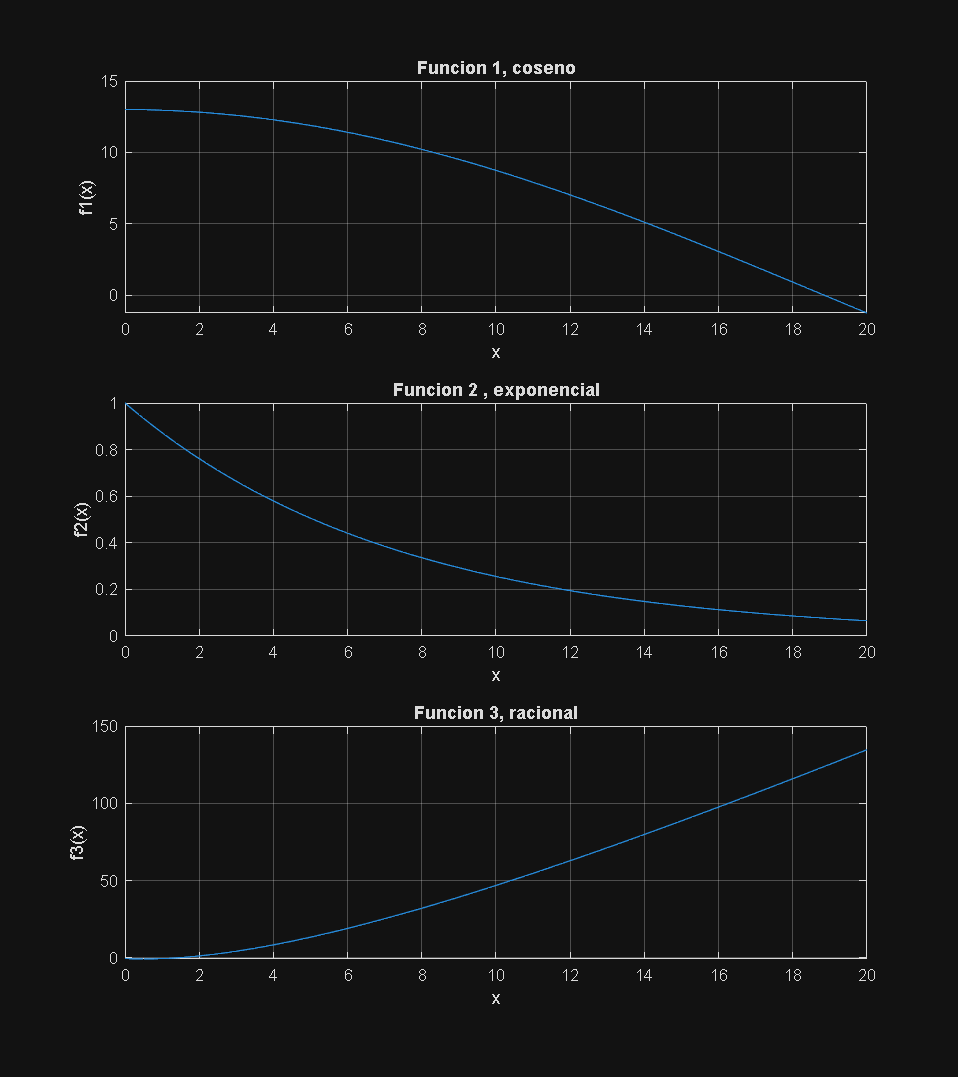

x = 0:0.1:20;
y1 = (p+2)*cos(x/(1+q));
y2 = r/5*exp(-3*x/(p+q));
y3 = (p*x.^2-q*x-r)./(x+q);

figure('Position',[100 100 800 900])
tiledlayout(3,1);
nexttile
plot(x, y1)            
xlabel('x')           
ylabel('f1(x)')      
title('Funcion 1, coseno')
grid on
nexttile
plot(x, y2)            
xlabel('x')           
ylabel('f2(x)')      
title('Funcion 2 , exponencial')
grid on
nexttile
plot(x, y3)            
xlabel('x')           
ylabel('f3(x)')      
title('Funcion 3, racional')
grid on

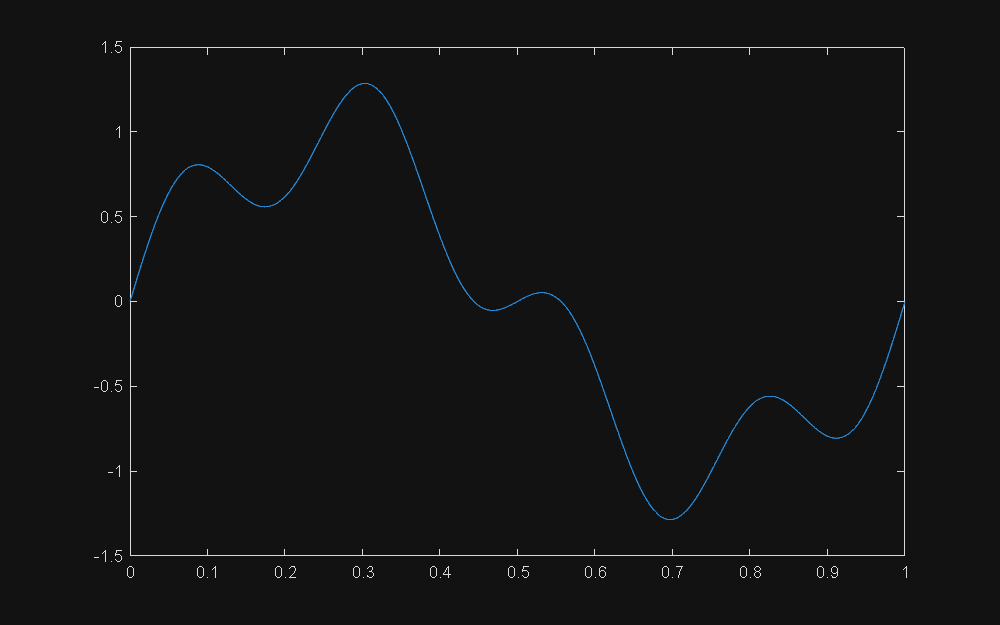


figure('Position',[100 100 800 500])
x = 0:0.001:1;
y = sin(2*pi*d(9).*x)+0.35*sin(8*pi*d(9).*x);   
x2 = 0:0.005:1;
y2 = sin(2*pi*d(9).*x2)+0.35*sin(8*pi*d(9).*x2); 
x3 = 0:0.03:1;
y3 = sin(2*pi*d(9).*x3)+0.35*sin(8*pi*d(9).*x3); 
x4 = 0:0.1:1;
y4 = sin(2*pi*d(9).*x4)+0.35*sin(8*pi*d(9).*x4); 
plot(x, y)

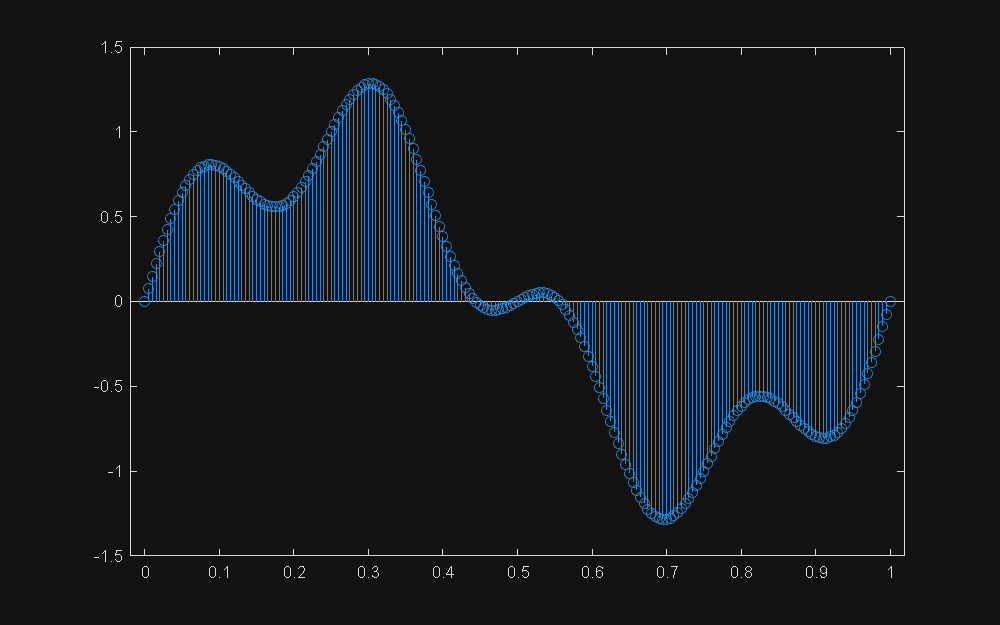

stem(x2,y2)

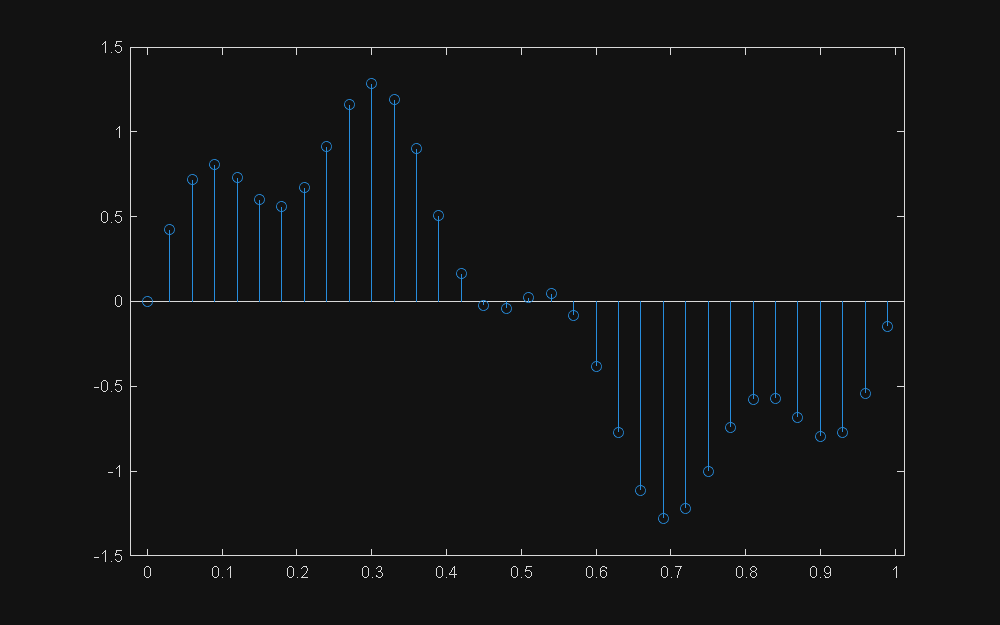

stem(x3,y3)

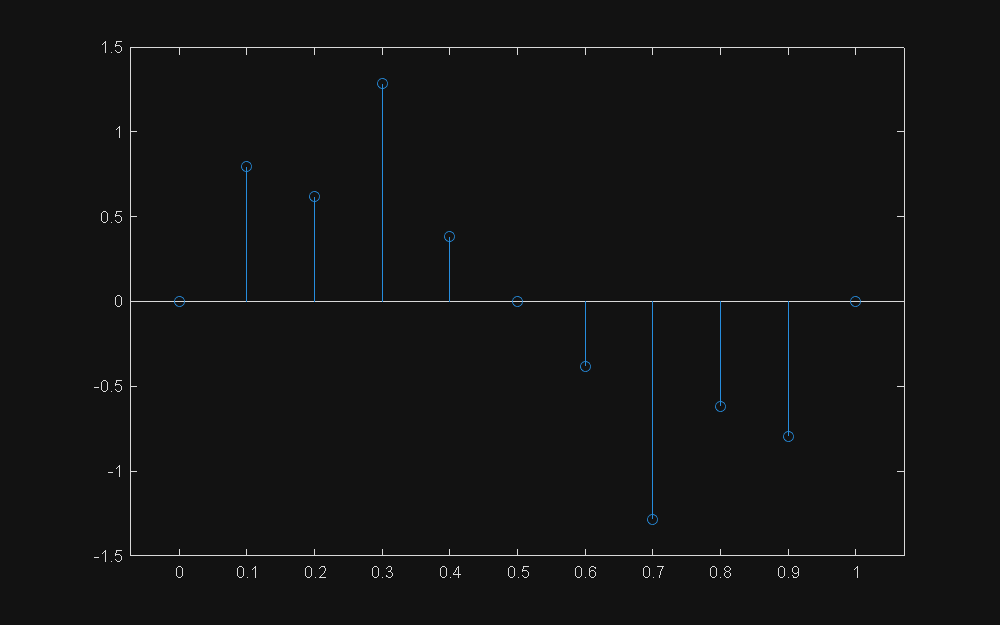

stem(x4,y4)

## Punto 4.

M = [-7 9 35 -3 16 12;
    15 5 15 98 54 -6;
    18 -1 13 57 -2 55;
    22 0 41 33 87 81;
    36 7 -4 15 69 -34;
    -9 65 70 -8 5 25]

M =     -7     9    35    -3    16    12
    15     5    15    98    54    -6
    18    -1    13    57    -2    55
    22     0    41    33    87    81
    36     7    -4    15    69   -34
    -9    65    70    -8     5    25



B = M(3,6)

B =     55


C = M(:,5)

C =     16
    54
    -2
    87
    69
     5


D = M(2:5,3:6)

D =     15    98    54    -6
    13    57    -2    55
    41    33    87    81
    -4    15    69   -34



e = [];
length(M)

ans =      6


for i = 1:length(M)
    e(end+1) = M(i,i);
end
e

e =     -7     5    13    33    69    25


F = [];
for i = 1:length(M)
    k = i;
    while k >= i && k<=length(M(i,:))
        F(end+1) = M(i,k);
        k = k+1;
    end
    
end
F

F =     -7     9    35    -3    16    12     5    15    98    54    -6    13    57    -2    55    33    87    81    69   -34    25


negativos = {};

for i = 1:length(M)
    for j = 1:length(M(1,:))
        if M(i,j) < 0
            negativos{end+1} = i + ", " + j;
        end
    end
end
negativos

negativos = 1×9 cell array
    {["1, 1"]}    {["1, 4"]}    {["2, 6"]}    {["3, 2"]}    {["3, 5"]}    {["5, 3"]}    {["5, 6"]}    {["6, 1"]}    {["6, 4"]}


suma = 0;

for i = 1:length(M)
    for j = 1:length(M(1,:))
        suma = suma + M(i,j);
    end
end

media_global = 1/(length(M)*length(M(1,:)))*suma

media_global =   24.555555555555554


max_1=0;
max_2=0;
max_3=0;

for i = 1:length(M)
    for j = 1:length(M(1,:))
        if abs(M(i,j)) > max_1
            max_1 = abs(M(i,j));
        elseif abs(M(i,j)) > max_2
            max_2 = abs(M(i,j));
        elseif abs(M(i,j)) > max_3
            max_3=abs(M(i,j));
        end
    end
end

max_1

max_1 =     98


max_2

max_2 =     87


max_3

max_3 =     81



Z = zeros(6, 6);

for j = 1:length(M(1,:))
    n = length(M(:,j));
    u_j = 1/n*sum(M(:,j));
    sigma_j = sqrt(1/(n-1)*sum((M(:,j)-u_j).^2));
    for i = 1:length(M)
        Z(i,j) = (M(i,j)-u_j)/(sigma_j);
    end
end
Z

Z =   -1.117850267774412  -0.204973742220589   0.255680064184295  -0.869796782408251  -0.601483692061360  -0.245156730681972
   0.143314136894155  -0.363663091036529  -0.511360128368590   1.640188218255560   0.429631208615257  -0.679204712873004
   0.315291101167142  -0.601697114260439  -0.588064147623878   0.621283416005894  -1.089906539750283   0.791735671218828
   0.544593720197791  -0.562024777056454   0.485792121950161   0.024851336640236   1.325073096044951   1.418693867716986
   1.347152886805061  -0.284318416628559  -1.240048311293831  -0.422472722884008   0.836650248356027  -1.354390462947944
  -1.232501577289737   2.016677141202571   1.598000401151844  -0.994053465609430  -0.899964321204591   0.068322367567107


%comprobacion de media y desviacion estandar

for j=1:length(Z(1,:))
    u=1/length(Z(:,j))*sum(Z(:,j))
    sigma = sqrt(1/(length(Z(:,j))-1)*sum((Z(:,j)-u).^2))
end

u =     -3.700743415417188e-17


sigma =    1.000000000000000


u =      0


sigma =    1.000000000000000


u =      7.401486830834377e-17


sigma =      1


u =     -1.850371707708594e-17


sigma =    1.000000000000000


u =      5.551115123125783e-17


sigma =    1.000000000000000


u =      4.394632805807911e-17


sigma =      1


% G = M1*M2 + M3T

M1 = [M(3,1) M(4,3); M(1,4) M(5,1)];
M2 = [M(2,3) M(2,5); M(6,3) M(1,5)];
M3 = [M(1,1) M(6,6); M(2,2) M(3,3)].';

G = M1*M2 + M3

G =         3133        1633
        2500         427
